## **Driver test program to check Clothoids library**

**Triangles**

% check constructors
x0 = 0; y0 = 0;
x1 = 4; y1 = 0;
x2 = 0; y2 = 7;

T1 = Triangle2D( x0, y0, x1, y1, x2, y2 );

figure('Position',[ 1 1 800 800]);

x     = -10:0.05:10;
y     = -5:0.05:15;
[X,Y] = meshgrid(x,y);

tic
Zmin = T1.distanceMin(X,Y);
toc

Elapsed time is 0.017001 seconds.



tic
Zmax = T1.distanceMax(X,Y);
toc

Elapsed time is 0.006813 seconds.


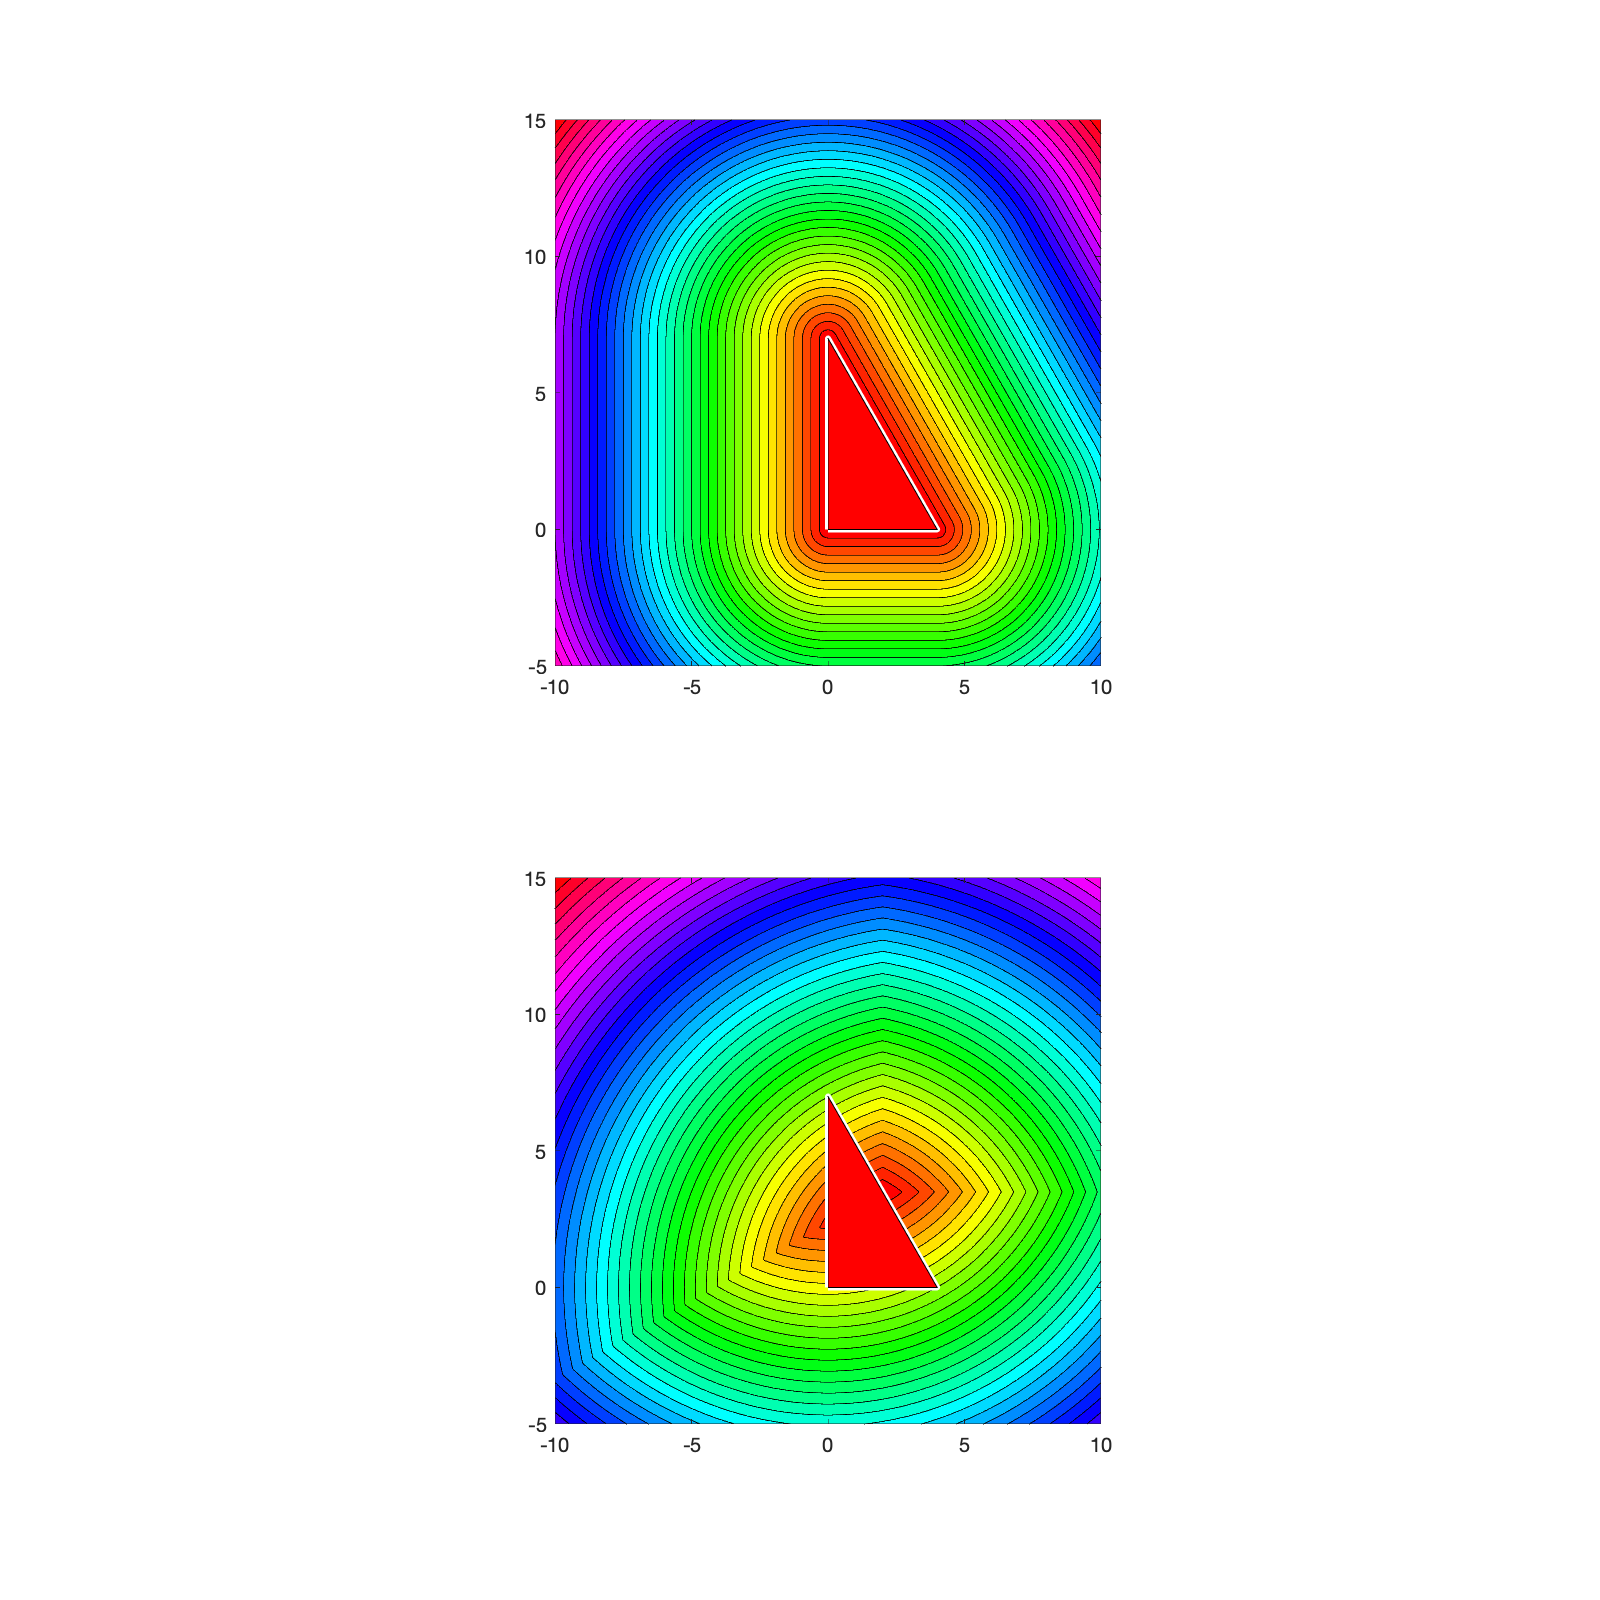


subplot(2,1,1);
colormap(hsv);
contourf(X,Y,Zmin,40);
hold on;
%surf(X,Y,Zmin)
axis equal;

hold on;
T1.plot('red','Color','white','Linewidth',3);
%
subplot(2,1,2);
colormap(hsv);
contourf(X,Y,Zmax,40);
hold on;
%surf(X,Y,Zmax)
axis equal;

hold on;
T1.plot('red','Color','white','Linewidth',3);

%